%Pretty condition
u = 30;
D = 4;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt+1;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx+1;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);

if (4*(alpha^2) < 2*beta && 2*beta < 1)
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability respected!


% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
T = zeros(n_step_space,n_step_time);
for i = 2:n_step_space-1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end

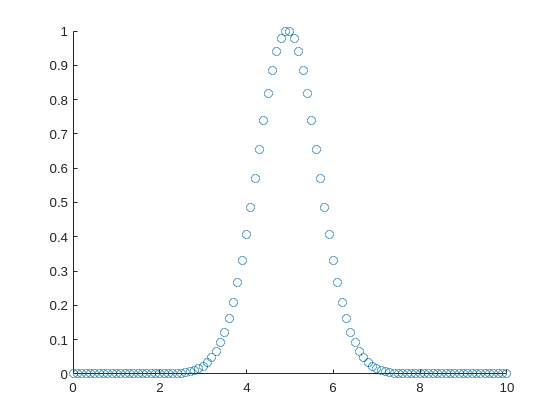


scatter(x, T(:,1))    

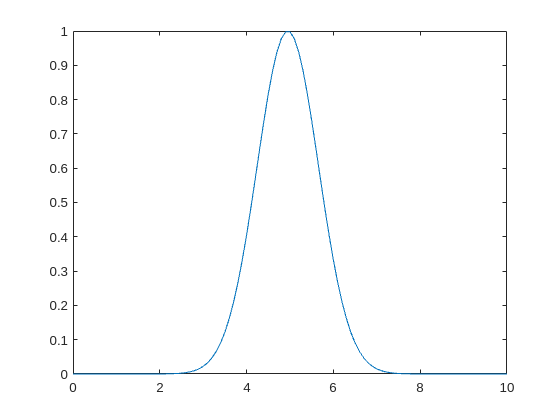

plot(x, T(:,1))

% Dirichlet condition solver
% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end
end


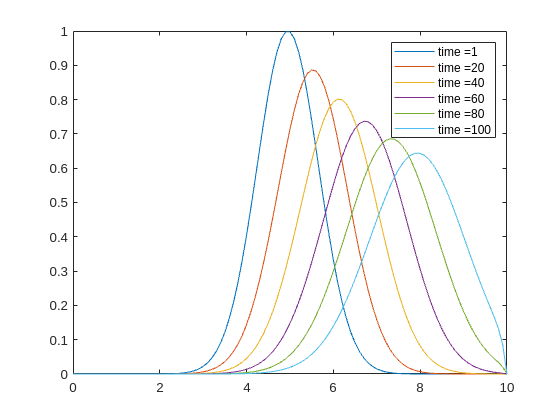

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(:, 1))
hold on
for j = 1:5
    plot(x, T(:,(j)*20));
    hold on
end
legend(Legend)
hold off

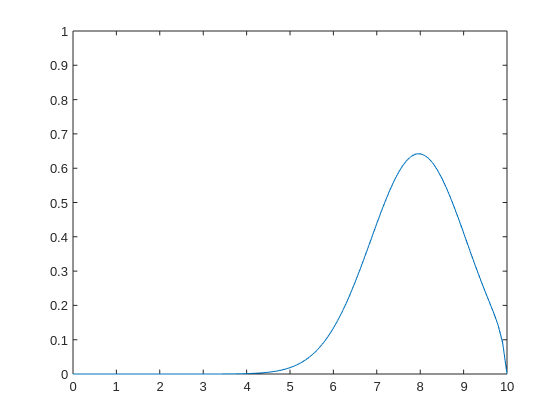

for j = 1:n_step_time
    plot(x, T(:,j))
    ylim([0,1])
    pause (0.1)
end

%Condizioni di Neumann
T = zeros(n_step_space+2,n_step_time);
for i = 2:n_step_space+1
    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end

T(1,1) = T(3,1);
T(n_step_space+2,1) = T(n_step_space,1);


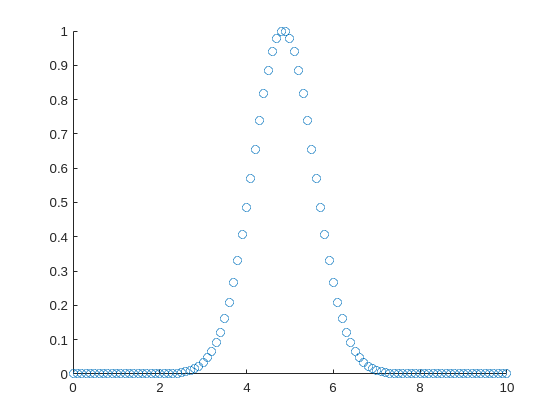

scatter(x, T(2:n_step_space+1,1))

% Nuemann condition solver
% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space+1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;

        T(1,j) = T(3,j);
        T(n_step_space+2,j) = T(n_step_space,j);

    end
end

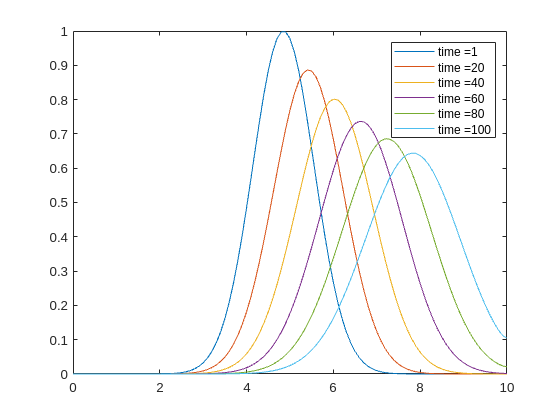

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(2:n_step_space+1, 1))
hold on
for j = 1:5
    plot(x, T(2:n_step_space+1,(j)*20));
    hold on
end
legend(Legend)
hold off

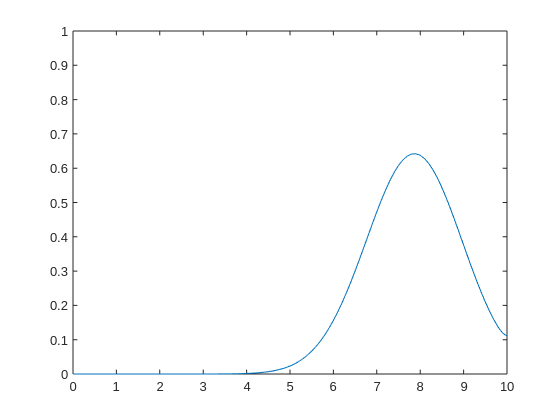

for j = 1:n_step_time
    plot(x, T(2:n_step_space+1,j));
    ylim([0,1])
    pause(0.1)
end